# External Description of LTI Systems: from the State-Space Representation to Transfer Functions

## Introduction

Consider an LTI system, described using the state-space representation


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& A\,x(t) + B\,u(t) \\
y(t) &=& C\,x(t) + D\,u(t)
\end{array} \right.$$


with


$$x(t) \in \mathbb{R}^n\,,\quad u(t) \in \mathbb{R}^m\,,\quad y(t) \in \mathbb{R}^p$$


Exploiting the Laplace transform and assuming that the system state at the initial time instant (i.e. $t=0$) is the null state $x(0) = \left[ 0 \; 0 \; \cdots 0 \right]^{\top}$, one can obtain the input/output description of the same LTI system (the so-called "external description" or "transfer functions matrix" ) simply as follows:


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& A\,x(t) + B\,u(t) \\
y(t) &=& C\,x(t) + D\,u(t)
\end{array} \right. \quad \Longrightarrow \quad 
\begin{array}{rcl}
G(s) &=& C \left( sI-A \right)^{-1} B+D \\
Y(s) &=& G(s)\, U(s)
\end{array}$$


By exploring this live script, you will learn how to calculate transfer functions, given a representation of the state space of an LTI system, using the Symbolic Math Toolbox or the available commands of the Control System Toolbox.

## Example 1: Constant Gain - an LTI SISO System

Consider the system (refer to Part 2 of the course material):

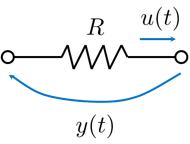

 There is no state and we can describe the system using the I/O description $y(t) = R\, u(t)$

### Symbolic Computation of the Transfer Function 

Starting from the state space equations:

clear


syms s % the complex frequency of the Laplace transform
syms R % the constant gain of the algebraic system (the resistance R)

% the matrices of the state space representation of the system
% Note: they are all symbolic scalars!
A = sym(0); B = sym(0);  % no state x, no dynamics for the first derivative of the state x
C = sym(0);              % no influence of the state x on the output y
D = R; % there is the algebraic link between the input u and the output y

syms G(s) % the symbolic expression of the transfer function

G(s) = C*( inv(s*eye(size(A))-A) )*B +D 

$$G(s) = R$$

### Numerical Calculation of the Transfer Function

What if we have a numerical description of the "resistor" system? Let us use the functions `ss( )` , `tf( )`  and `zpk( )` from the Control System Toolbox. 

clear

Rval = 1e3; % 1000 Ohm

A = 0; B= 0; C = 0; D = Rval; % the LTI system matrices in the state space equations

resistorStateEq = ss(A, B, C, D) % let's obtain the state space description


resistorStateEq =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   0
 
  C = 
       x1
   y1   0
 
  D = 
         u1
   y1  1000
 
Continuous-time state-space model.
Model Properties



resistorTF = tf(resistorStateEq) % let's convert to the transfer function!


resistorTF =
 
  1000
 
Static gain.
Model Properties


resistorZPK = zpk(resistorTF) % a different visualisation of the same transfer function


resistorZPK =
 
  1000
 
Static gain.
Model Properties


                              % indeed not so different, this time!

## Example 2: a First Order Strictly Proper LTI SISO System

Consider the system (refer to Part 2 of the course material) 

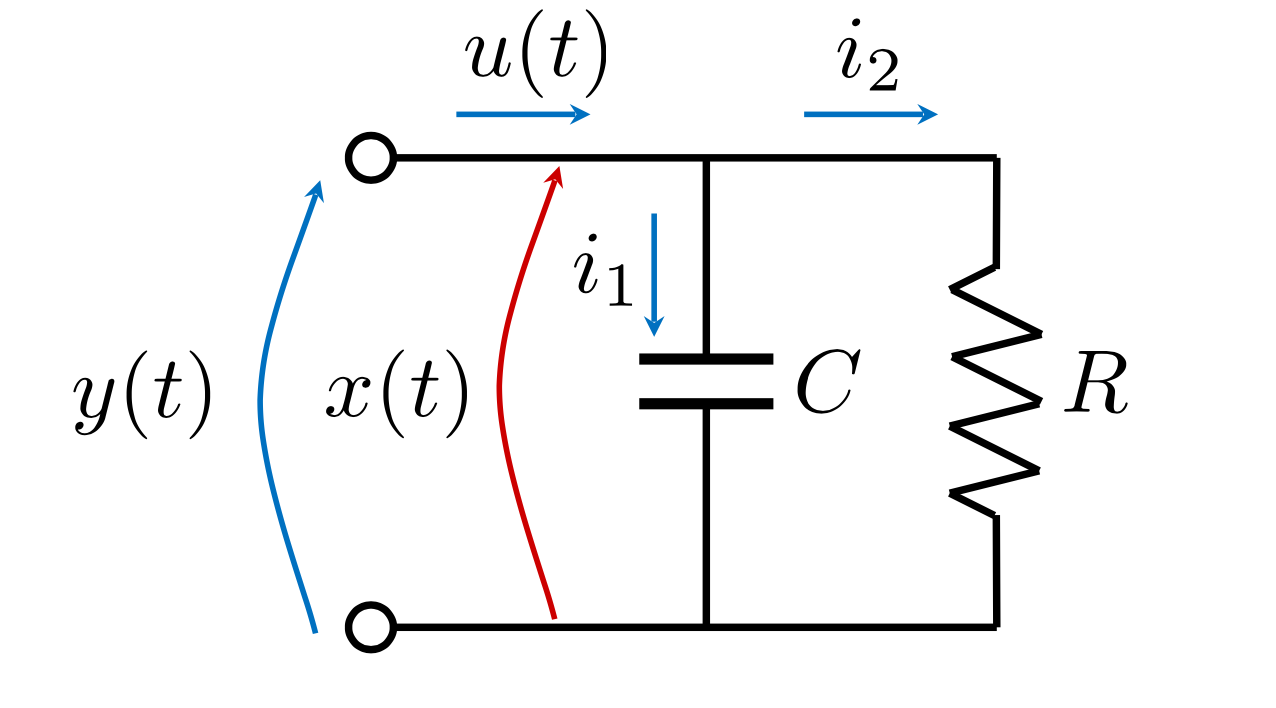

The state equations are


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& -\frac{1}{RC} x(t) + \frac{1}{C} u(t) \\
y(t) &=& x(t)
\end{array} \right.$$


### Symbolic Computation of the Transfer Function 

Starting from the state space equations:

clear

syms s % the complex frequency of the Laplace transform
syms R % the resistance R
syms C % the capacity C

% the matrices of the state space representation of the system
% Note: they are all symbolic scalars!
Amat = -1/(R*C); Bmat = 1/C;  % the state dynamics 
Cmat = sym(1);                % the link between the state x and the output y
Dmat = sym(0); % there is NO algebraic link between the input u and the output y

syms G(s) % the symbolic expression of the transfer function
sI_A = s*eye(size(Amat))-Amat;
sI_A_INV = inv(sI_A);
G(s) = Cmat*sI_A_INV*Bmat +Dmat   

$$G(s) = \frac{1}{C\,\left(s+\frac{1}{C\,R}\right)}$$

p_G = poles(G) % what are the poles of the transfer function?

$$p\_G = -\frac{1}{C\,R}$$

### Numerical Calculation of the Transfer Function

What if we have a numerical description of the "resistor" system? Let us use the functions `ss( )` , `tf( )`  and `zpk( )` from the Control System Toolbox. 


clear

Rval = 1e3; % 1000 Ohm
Cval = 1e-2;% 0.01 F

A = -1/(Rval*Cval); B= 1/Cval; C = 1; D = 0; % the LTI system matrices in the state space equations

RCparallelStateEq = ss(A, B, C, D) % let's obtain the state space description


RCparallelStateEq =
 
  A = 
         x1
   x1  -0.1
 
  B = 
        u1
   x1  100
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


RCparallelTF = tf(RCparallelStateEq) % let's convert to the transfer function!


RCparallelTF =
 
    100
  -------
  s + 0.1
 
Continuous-time transfer function.
Model Properties


p1G = pole(RCparallelTF) % What are the poles of the transfer function?

p1G = -0.1000



RCparallelZPK = zpk(RCparallelTF) % a different visualisation of the same transfer function


RCparallelZPK =
 
    100
  -------
  (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


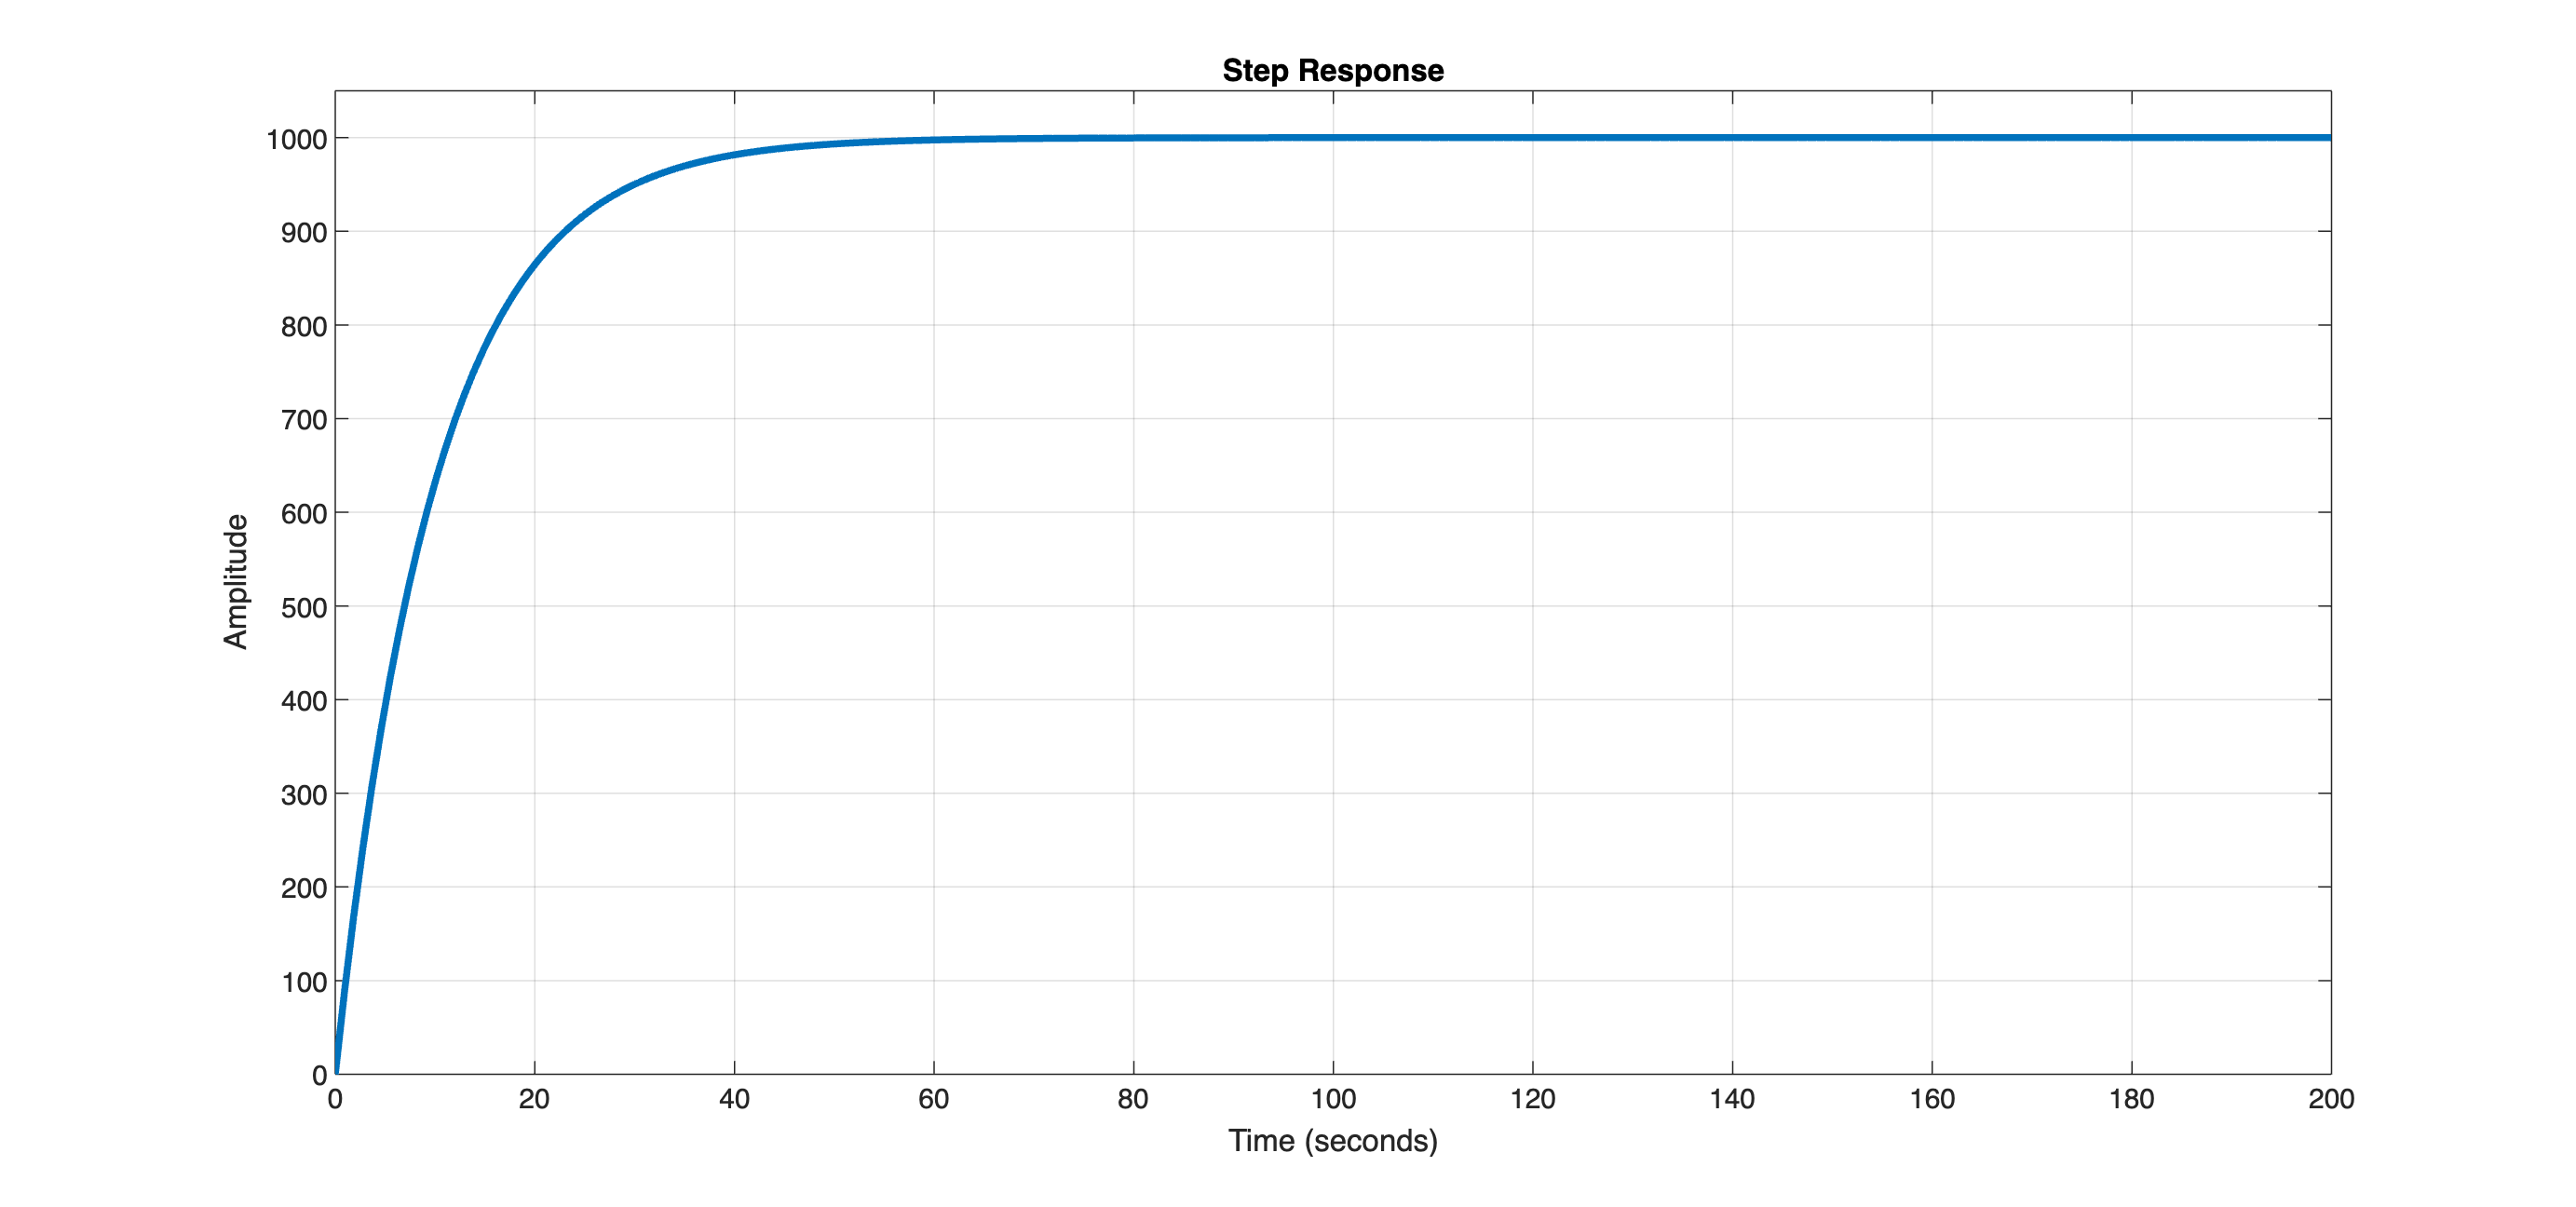

Tfinal = 200;
[yp, tp] = step(RCparallelZPK , Tfinal);
figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.9, 0.75]);
plot(tp, yp, 'LineWidth', 2.5); grid on; zoom on;
xlabel('Time (seconds)'); ylabel('Amplitude');
xlim([0, Tfinal]); ylim([0, 1.05*max(yp)]);
title('Step Response');


RCparStepInfo = stepinfo(RCparallelZPK, "SettlingTimeThreshold", 0.01)

RCparStepInfo = struct with fields:
         RiseTime: 21.9701
    TransientTime: 46.0517
     SettlingTime: 46.0517
      SettlingMin: 904.5007
      SettlingMax: 999.3393
        Overshoot: 0
       Undershoot: 0
             Peak: 999.3393
         PeakTime: 73.2222

For details

## Example 3: a First Order  NOT Strictly Proper LTI SISO System

Consider the system (refer to Part 2 of the course material) 

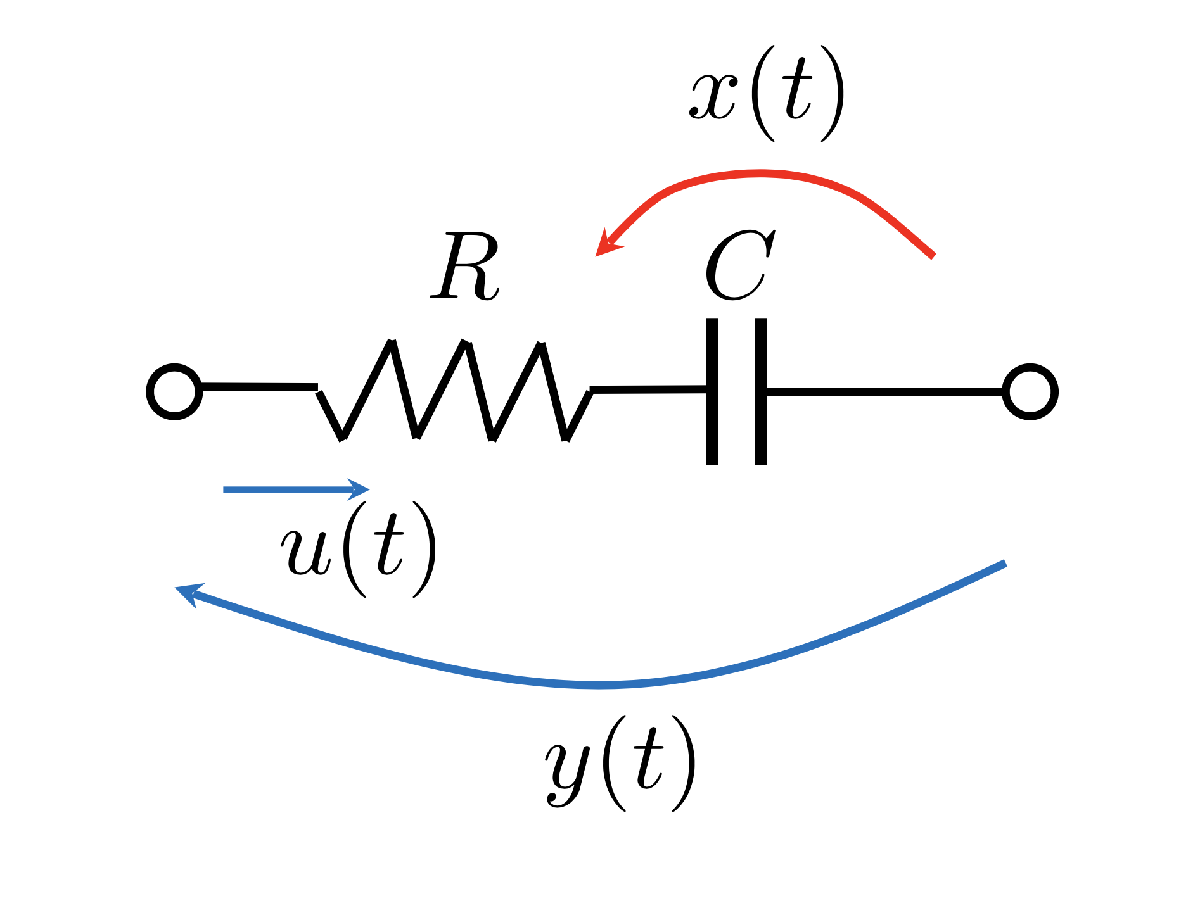

A description using state equations is as follows


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=&  \frac{1}{C} u(t) \\
y(t) &=& x(t) + R u(t)
\end{array} \right.$$


### Symbolic Computation of the Transfer Function 

Starting from the state space equations:

clear

syms s % the complex frequency of the Laplace transform
syms R % the resistance R
syms C % the capacity C

% the matrices of the state space representation of the system
% Note: they are all symbolic scalars!
Amat = sym(0); Bmat = 1/C;  % the state dynamics 
Cmat = sym(1);              % the link between the state x and the output y
Dmat = R; % there is algebraic link between the input u and the output y

syms G(s) % the symbolic expression of the transfer function
sI_A = s*eye(size(Amat))-Amat;
sI_A_INV = inv(sI_A);
G(s) = Cmat*sI_A_INV*Bmat +Dmat 

$$G(s) = R+\frac{1}{C\,s}$$


p_G = poles(G) % what are the poles of the transfer function?

$$p\_G = 0$$

### Numerical Calculation of the Transfer Function

What if we have a numerical description of the "RC series" system? Let us use the functions `ss( )` , `tf( )`  and `zpk( )` from the Control System Toolbox. 

clear

Rval = 1e3; % 1000 Ohm
Cval = 1e-2;% 0.01 F

A = 0; B= 1/Cval; C = 1; D = Rval; % the LTI system matrices in the state space equations

RCseriesStateEq = ss(A, B, C, D) % let's obtain the state space description


RCseriesStateEq =
 
  A = 
       x1
   x1   0
 
  B = 
        u1
   x1  100
 
  C = 
       x1
   y1   1
 
  D = 
         u1
   y1  1000
 
Continuous-time state-space model.
Model Properties



RCseriesTF = tf(RCseriesStateEq) % let's convert to the transfer function!


RCseriesTF =
 
  1000 s + 100
  ------------
       s
 
Continuous-time transfer function.
Model Properties


p1G = pole(RCseriesTF) % What are the poles of the transfer function?

p1G = 0



RCseriesZPK = zpk(RCseriesTF) % a different visualisation of the same transfer function


RCseriesZPK =
 
  1000 (s+0.1)
  ------------
       s
 
Continuous-time zero/pole/gain model.
Model Properties


## Example 4: a Second Order Strictly Proper LTI SISO System

Consider the system (refer to Part 2 of the course material) 

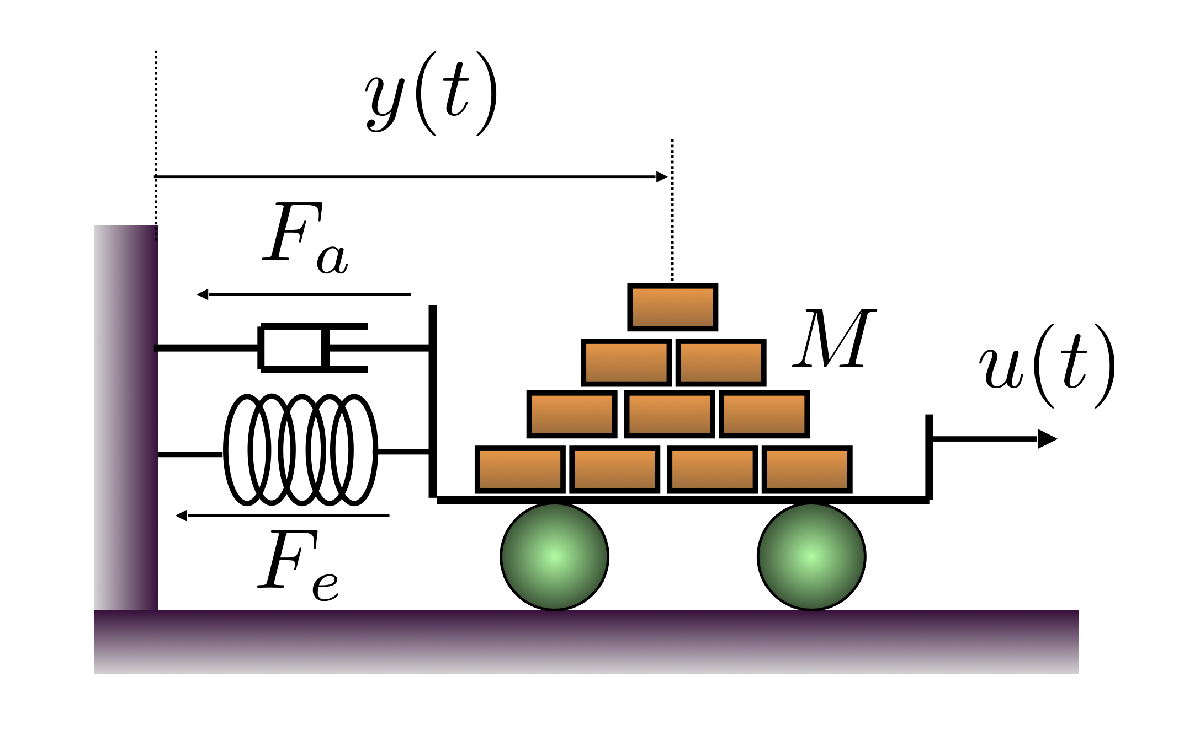

A description using state equations is as follows


$$\left\{ \begin{array}{rcl}
\dot{x}_{1}(t) &=&  x_2(t) \\
\dot{x}_{2}(t) &=& -\frac{k}{M} x_1(t)-\frac{h}{M} x_2(t) +\frac{1}{M} u(t)\\
y(t) &=& x_1(t) 
\end{array} \right.$$


### Symbolic Computation of the Transfer Function 

Starting from the state space equations:

clear

syms s % the complex frequency of the Laplace transform
syms k h M % the parameters of the mass-spring-damper system


% the matrices of the state space representation of the system
% Note: they are all symbolic scalars!
Amat = [   0  1;
        -k/M   -h/M];
Bmat = [0; 1/M];      % the state dynamics 
Cmat = sym([1 0]);    % the link between the state x and the output y
Dmat = sym(0); % there is NO algebraic link between the input u and the output y

syms G(s) % the symbolic expression of the transfer function
sI_A = s*eye(size(Amat))-Amat;
sI_A_INV = inv(sI_A);
G(s) = Cmat*sI_A_INV*Bmat +Dmat 

$$G(s) = \frac{1}{M\,s^{2}+h\,s+k}$$


p_G = poles(G) % what are the poles of the transfer function?

$$p\_G = \left[\begin{array}{c} -\frac{h-\sqrt{h^{2}-4\,M\,k}}{2\,M}\\ -\frac{h+\sqrt{h^{2}-4\,M\,k}}{2\,M} \end{array}\right]$$

### Numerical Calculation of the Transfer Function

What if we have a numerical description of the "mass-spring-damper" system? Let us use the functions `ss( )` , `tf( )`  and `zpk( )` from the Control System Toolbox. 

clear

M = 123.52; % kg [cart mass]
h = 9.12;   % Ns/m [damping constant]
k = 10.09;  % N/m [spring elastic coeff.] <-- change the value
            % use for instance k = 10.89    
% using this set of params --> roots([M h k]) complex conj.

A = [   0      1;
     -k/M   -h/M]; 
B = [0; 1/M];
C = [1 0]; 
D = 0; % the LTI system matrices in the state space equations

cartSpringDamper_StateEq = ss(A, B, C, D) % let's obtain the state space description


cartSpringDamper_StateEq =
 
  A = 
             x1        x2
   x1         0         1
   x2  -0.08169  -0.07383
 
  B = 
             u1
   x1         0
   x2  0.008096
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



cartSpringDamper_TF = tf(cartSpringDamper_StateEq) % let's convert to the transfer function!


cartSpringDamper_TF =
 
          0.008096
  -------------------------
  s^2 + 0.07383 s + 0.08169
 
Continuous-time transfer function.
Model Properties


p1G = pole(cartSpringDamper_TF) % What are the poles of the transfer function?

p1G =   -0.0369 + 0.2834i
  -0.0369 - 0.2834i




cartSpringDamper_ZPK = zpk(cartSpringDamper_TF) % a different visualisation of the same transfer function


cartSpringDamper_ZPK =
 
          0.0080959
  --------------------------
  (s^2 + 0.07383s + 0.08169)
 
Continuous-time zero/pole/gain model.
Model Properties


## Example 5: a Fourth Order Strictly Proper LTI MIMO System

Consider the system (refer to the live script  HandsON_StateSpaceDescription.mlx - Part 2 of the course material) 

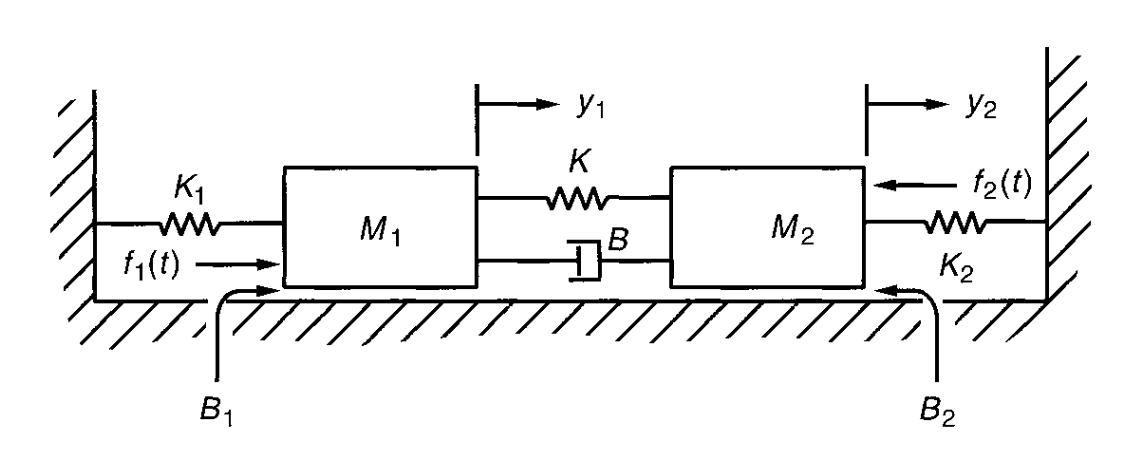

 The dynamics of the system is given by the state-space model derived from conservation balances (of mass, energy, etc.). Applying Newton's second law, we obtain the following state-space description:


$$\left\{ \begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\ \dot{x}_2(t) \\ \dot{x}_3(t) \\ \dot{x}_4 (t)
\end{array} \right] &=& \left[ \begin{array}{cccc} 
0 & 1 & 0 & 0 \\[0.5em]
-\displaystyle \frac{K_1+K}{M_1} & -\displaystyle \frac{B_1+B}{M_1} & \displaystyle \frac{K}{M_1} & \displaystyle \frac{B}{M_1} \\[0.5em]
0 & 0 & 0 & 1 \\[0.5em]
 \displaystyle \frac{K}{M_2} & \displaystyle \frac{B}{M_2} &-\displaystyle \frac{K_2+K}{M_2} & -\displaystyle \frac{B_2+B}{M_2}
\end{array} \right] \, \left[ \begin{array}{c}
x_1(t) \\ x_2(t) \\ x_3(t) \\ x_4 (t)
\end{array} \right] \, + \, 
\left[ \begin{array}{cc}
0 & 0 \\[0.5em]
\displaystyle \frac{1}{M_1} & 0 \\[0.5em]
0 & 0 \\[0.5em]
0 & \displaystyle -\frac{1}{M_2} 
\end{array} \right] \, \left[ \begin{array}{c}
f_1(t) \\[0.5em]
f_2(t) 
\end{array} \right] \\[0.75em] \\
\left[ \begin{array}{c}
y_1(t) \\[0.5em]
y_2(t) 
\end{array} \right] &=& \left[ \begin{array}{cccc}
1 & 0 & 0 &0\\[0.5em]
0 & 0 & 1 & 0
\end{array} \right] \, \left[ \begin{array}{c}
x_1(t) \\ x_2(t) \\ x_3(t) \\ x_4 (t)
\end{array} \right] 
\end{array} \right.$$


where the state variables are


$$\left\{ \begin{array}{lcl}
x_1(t) &=& y_1(t) \\
x_2(t) &=& \dot{y}_1(t) \\
x_3(t) &=& y_2(t) \\
x_4(t) &=& \dot{y}_2(t)
\end{array} \right.$$


Use the following parameters to configure the system model:

- point masses [kg]: $M_1 = 1.0$ , and $M_2 = 2.5$;

- viscous damping coefficients [N s/m]: $B = 3.60 \cdot 10^{-3}\, , \quad B_1 = 5.0 \cdot 10^{-2}\, , \quad B_2 = 5.0 \cdot 10^{-2}\$;

- spring constants [N/m] : $K = 9.1 \cdot 10^{-2}\, , \quad K_1 = 1.0 \cdot 10^{-1}\, , \quad K_2 = 1.0 \cdot 10^{-1}$.

### Symbolic Computation of the Transfer Functions Matrix

Starting from the state space equations:

clear

syms s % the complex frequency of the Laplace transform
syms K K1 K2 % the parameters of the 2masses-springs-dampers system
syms B B1 B2 % the parameters of the 2masses-springs-dampers system
syms M1 M2   % the parameters of the 2masses-springs-dampers system

% the matrices of the state space representation of the system
% Note: they are all symbolic scalars!
Amat = [      0          1       0              0;
         -(K+K1)/M1 -(B+B1)/M1   K/M1          B/M1;
              0          0       0              1;
            K/M2      B/M2    -(K+K2)/M2    -(B+B2)/M2];

Bmat = [   0     0;
         1/M1    0;
           0     0;
           0   -1/M2];   
% the state dynamics 


Cmat = sym([1  0  0  0;
            0  0  1  0]);    % the link between the state x and the output y

Dmat = sym([0  0; ...
             0  0 ]); % there is NO algebraic link between the input u and the output y

syms G(s) % the symbolic expression of the transfer function
sI_A = s*eye(size(Amat))-Amat;
sI_A_INV = inv(sI_A);
G(s) = simplify(collect(Cmat*sI_A_INV*Bmat +Dmat,s) )

$$G(s) = \begin{array}{l} \left[\begin{array}{cc} \frac{M_{2}\,s^{2}+\left(B+B_{2}\right)\,s+K+K_{2}}{\sigma_{1}} & -\frac{K+B\,s}{M_{1}\,M_{2}\,s^{4}+\sigma_{4}+\sigma_{2}+\sigma_{3}+K\,K_{1}+K\,K_{2}+K_{1}\,K_{2}}\\ \frac{B\,s+K}{\sigma_{1}} & \frac{\left(-M_{1}\right)\,s^{2}+\left(-B-B_{1}\right)\,s-K-K_{1}}{\sigma_{1}} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\left(M_{1}\,M_{2}\right)\,s^{4}+\sigma_{4}+\sigma_{2}+\sigma_{3}+K\,K_{1}+K\,K_{2}+K_{1}\,K_{2}\\ \sigma_{2}=\left(B\,B_{1}+B\,B_{2}+B_{1}\,B_{2}+K\,M_{1}+K\,M_{2}+K_{1}\,M_{2}+K_{2}\,M_{1}\right)\,s^{2}\\ \sigma_{3}=\left(B\,K_{1}+B_{1}\,K+B\,K_{2}+B_{2}\,K+B_{1}\,K_{2}+B_{2}\,K_{1}\right)\,s\\ \sigma_{4}=\left(B\,M_{1}+B\,M_{2}+B_{1}\,M_{2}+B_{2}\,M_{1}\right)\,s^{3} \end{array}$$

### Numerical Calculation of the Transfer Functions Matrix

What if we have a numerical description of the "mass-spring-damper" system? Let us use the functions `ss( )` , `tf( )`  and `zpk( )` from the Control System Toolbox. 

clear

M1 = 1;   % [kg]
M2 = 2.5; % [kg]
B  = 3.60e-3; % [N s/m]
B1 = 5e-2;    % [N s/m]
B2 = 5e-2;    % [N s/m]

K  = 9.1e-2; % [N/m]
K1 = 1e-1;   % [N/m]
K2 = 1e-1;   % [N/m]

Amat = [      0          1       0              0;
         -(K+K1)/M1 -(B+B1)/M1   K/M1          B/M1;
              0          0       0              1;
            K/M2      B/M2    -(K+K2)/M2    -(B+B2)/M2];

Bmat = [   0     0;
         1/M1    0;
           0     0;
           0   -1/M2];

Cmat = [1  0  0  0;
        0  0  1  0];

Dmat = [0  0 ;
     0   0 ]; % the LTI system matrices in the state space equations

TwoCartSpringDamper_StateEq = ss(Amat, Bmat, Cmat, Dmat) % let's obtain the state space description


TwoCartSpringDamper_StateEq =
 
  A = 
             x1        x2        x3        x4
   x1         0         1         0         0
   x2    -0.191   -0.0536     0.091    0.0036
   x3         0         0         0         1
   x4    0.0364   0.00144   -0.0764  -0.02144
 
  B = 
         u1    u2
   x1     0     0
   x2     1     0
   x3     0     0
   x4     0  -0.4
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



TwoCartSpringDamper_TF = tf(TwoCartSpringDamper_StateEq) % let's convert to the transfer function!


TwoCartSpringDamper_TF =
 
  From input 1 to output...
                     s^2 + 0.02144 s + 0.0764
   1:  -----------------------------------------------------
       s^4 + 0.07504 s^3 + 0.2685 s^2 + 0.007928 s + 0.01128
 
                        0.00144 s + 0.0364
   2:  -----------------------------------------------------
       s^4 + 0.07504 s^3 + 0.2685 s^2 + 0.007928 s + 0.01128
 
  From input 2 to output...
                        -0.00144 s - 0.0364
   1:  -----------------------------------------------------
       s^4 + 0.07504 s^3 + 0.2685 s^2 + 0.007928 s + 0.01128
 
                   -0.4 s^2 - 0.02144 s - 0.0764
   2:  -----------------------------------------------------
       s^4 + 0.07504 s^3 + 0.2685 s^2 + 0.007928 s + 0.01128
 
Continuous-time transfer function.


p1G = pole(TwoCartSpringDamper_TF) % What are the poles of the transfer function?

p1G =   -0.0252 + 0.4628i
  -0.0252 - 0.4628i
  -0.0123 + 0.2288i
  -0.0123 - 0.2288i
  -0.0252 + 0.4628i
  -0.0252 - 0.4628i
  -0.0123 + 0.2288i
  -0.0123 - 0.2288i




TwoCartSpringDamper_ZPK = zpk(TwoCartSpringDamper_TF) % a different visualisation of the same transfer function


TwoCartSpringDamper_ZPK =
 
  From input 1 to output...
                    (s^2 + 0.02144s + 0.0764)
   1:  ----------------------------------------------------
       (s^2 + 0.02457s + 0.05252) (s^2 + 0.05047s + 0.2148)
 
                        0.00144 (s+25.28)
   2:  ----------------------------------------------------
       (s^2 + 0.02457s + 0.05252) (s^2 + 0.05047s + 0.2148)
 
  From input 2 to output...
                        -0.00144 (s+25.28)
   1:  ----------------------------------------------------
       (s^2 + 0.02457s + 0.05252) (s^2 + 0.05047s + 0.2148)
 
                   -0.4 (s^2 + 0.0536s + 0.191)
   2:  ----------------------------------------------------
       (s^2 + 0.02457s + 0.05252) (s^2 + 0.05047s + 0.2148)
 
Continuous-time zero/pole/gain model.
